layers = [
    imageInputLayer([32 32 3])

1st conv layer

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

2nd conv layer

    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2) 

3rd conv layer

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2) 

4th conv layer

    % convolution2dLayer(3,256,'Padding','same')
    % batchNormalizationLayer
    % reluLayer
    % convolution2dLayer(3,256,'Padding','same')
    % batchNormalizationLayer
    % reluLayer
    % 
    

Classifier

    globalAveragePooling2dLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
];


global trainingInfo




fprintf('\n=== Running Training %d ===\n', expNum);


=== Running Training 1 ===


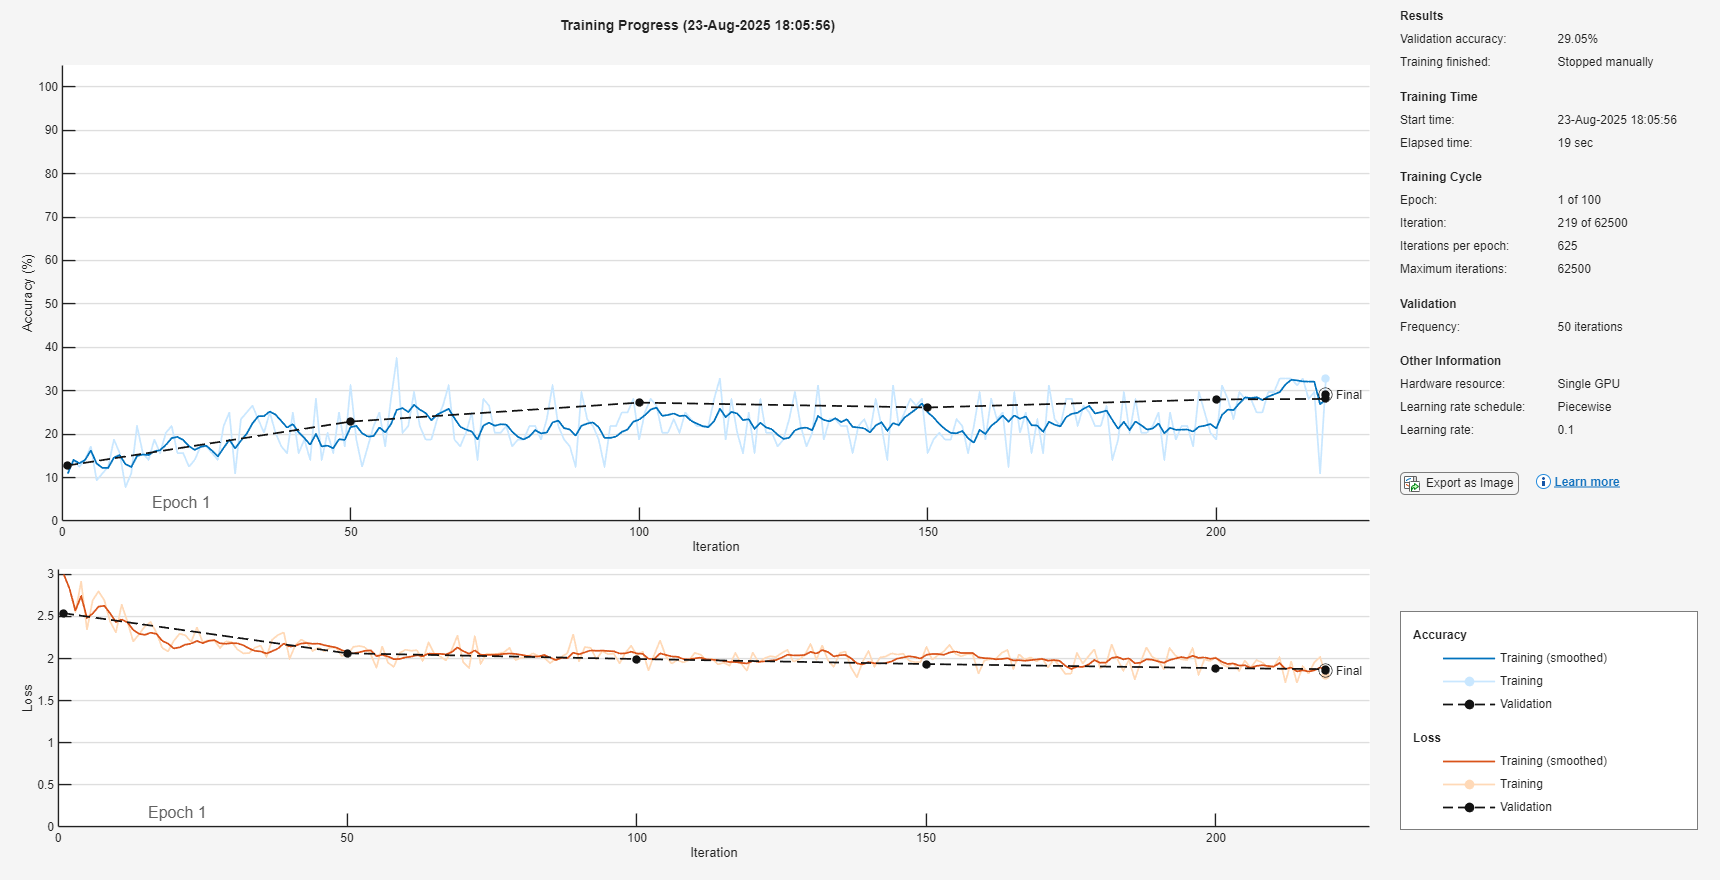

[net,trainingInfo] = trainNetwork(trainDS, layers, options);

fprintf('\n=== Done Training %d ===\n', expNum);


=== Done Training 1 ===


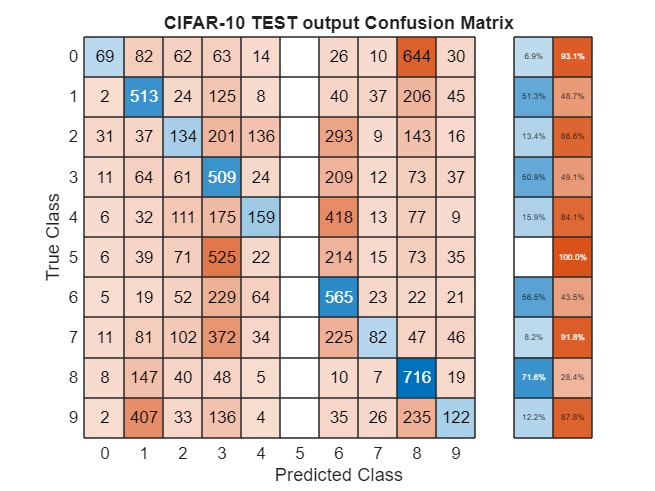

% Create confusion matrix
figure;
YPred = classify(net, testDS);
cm = confusionchart(testLabels, YPred);
cm.Title = 'CIFAR-10 TEST output Confusion Matrix';
cm.RowSummary = 'row-normalized'; % shows per-class accuracy in %

cmMatrix = cm.NormalizedValues;  % row-normalized values (0-1)
numPerClass = sum(cmMatrix,2);        % for normalized it's 1 per row, skip
overallAcc = sum(diag(cmMatrix));    % average of diagonal = average per-class accuracy
acc = num2str(overallAcc*(100/10000));


baseFilename = sprintf('3CONV_CIFAR10_%s_LR%.0e_BS%d_E%d_ACC%.2f', ...
                       mm,...
                       options.InitialLearnRate, ...
                       options.MiniBatchSize, ...
                       options.MaxEpochs,...
                       overallAcc/100);


outputFolder = fullfile('Test Output', baseFilename);
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
save(fullfile(outputFolder, [baseFilename '.mat']), 'net');

saveas(gcf, fullfile(outputFolder, 'CM.png'));

disp(['Overall Accuracy (from CM): ' acc '%']);

Overall Accuracy (from CM): 28.69%


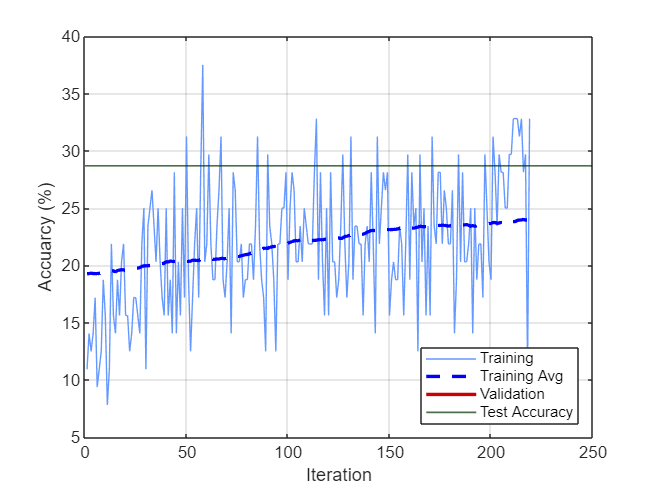

numIterationsPerEpoch = length(trainingInfo.TrainingLoss) / length(trainingInfo.ValidationLoss);
 figure;
    plot(1:length(trainingInfo.TrainingAccuracy), trainingInfo.TrainingAccuracy, 'Color', [0.4 0.6 1], 'LineWidth', 0.1); 
    hold on;
    
    avgTrainAcc = movmean(trainingInfo.TrainingAccuracy, 150);  
    plot(1:length(avgTrainAcc), avgTrainAcc,'--', 'Color', [0 0 1], 'LineWidth', 2);

    plot(1:numIterationsPerEpoch:length(trainingInfo.TrainingAccuracy), trainingInfo.ValidationAccuracy,'Color', [0.8 0 0], 'LineWidth', 2);
    yline(overallAcc/100, '-', 'Color', [0 0.2 0], 'LineWidth', 1);
    grid();
    xlabel('Iteration'); ylabel('Accuarcy (%)');
    legend('Training','Training Avg','Validation','Test Accuracy', 'Location', 'southeast');
    saveas(gcf, fullfile(outputFolder,'AccuarcyCurves.png'));
hold off;

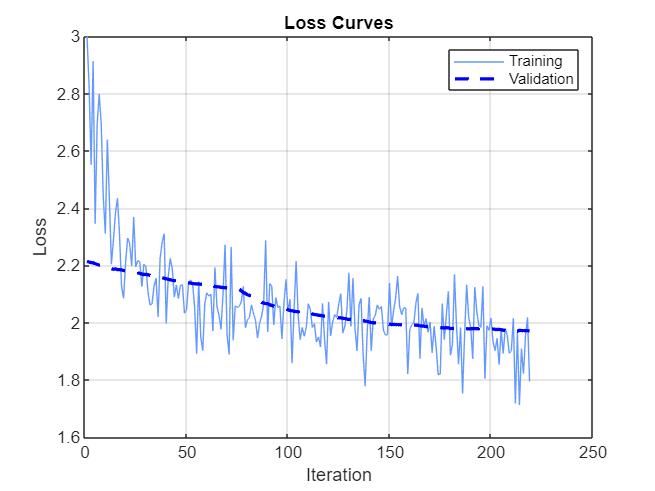

figure;
    plot(1:length(trainingInfo.TrainingLoss), trainingInfo.TrainingLoss, 'Color', [0.4 0.6 1],'LineWidth',0.1); hold on;
    
    avgTrainloss = movmean(trainingInfo.TrainingLoss, 150);  
    plot(1:length(avgTrainloss), avgTrainloss,'--', 'Color', [0 0 1], 'LineWidth', 2);

    plot(1:numIterationsPerEpoch:length(trainingInfo.TrainingLoss), trainingInfo.ValidationLoss,'Color',[0.8 0 0],'LineWidth',2);
    xlabel('Iteration'); ylabel('Loss');
    grid();
    legend('Training','Validation'); title('Loss Curves');
    saveas(gcf, fullfile(outputFolder,'LossCurves.png'));

layerFile = fullfile(outputFolder, [baseFilename '_Layers.csv']);
fid = fopen(layerFile, 'w');

% Write header
fprintf(fid, 'Index,LayerType,OutputSize,NumLearnableParams\n');

for i = 1:length(layers)
    layerInfo = layers(i);
    
    % Layer type
    typeStr = class(layerInfo);
    
    % Output size
    if isprop(layerInfo,'OutputSize')
        outSize = mat2str(layerInfo.OutputSize);
    else
        outSize = '';
    end
    
    % Number of learnable parameters
    if isprop(layerInfo,'NumLearnableParameters')
        numParams = layerInfo.NumLearnableParameters;
    else
        numParams = 0;
    end
    
    fprintf(fid, '%d,%s,%s,%d\n', i, typeStr, outSize, numParams);
end

fclose(fid);

clear cm fid acc
cm = confusionmat(testLabels, YPred);  
acc = mean(YPred(:) == testLabels(:));
numClasses = size(cm,1);
precision = zeros(numClasses,1);
recall = zeros(numClasses,1);
f1 = zeros(numClasses,1);

for c = 1:numClasses
    tp = cm(c,c);
    fp = sum(cm(:,c)) - tp;
    fn = sum(cm(c,:)) - tp;
    
    precision(c) = tp / (tp + fp + eps);
    recall(c)    = tp / (tp + fn + eps);
    f1(c)        = 2 * (precision(c)*recall(c)) / (precision(c)+recall(c)+eps);
end

% Macro averages
macroPrecision = mean(precision);
macroRecall = mean(recall);
macroF1 = mean(f1);

% Write results to text file in subfolder
resultsFile = fullfile(outputFolder,'results.txt');
fid = fopen(resultsFile,'w');
fprintf(fid,'Model\t: %s\n',baseFilename);
fprintf(fid,'Accuracy\t: %2.2f%%\n', acc*100);
fprintf(fid,'Precision\t: %2.2f%%\n', macroPrecision*100);
fprintf(fid,'Recall\t\t: %2.2f%%\n', macroRecall*100);
fprintf(fid,'F1 Score\t: %2.2f%%\n', macroF1*100);
fprintf(fid,'\nClass-wise metrics:\n');
for c = 1:numClasses
    fprintf(fid,'Class %d ->\tPrecision: %2.2f%%\t, Recall: %2.2f%%\t, F1: %2.2f%%\n', ...
        c-1, precision(c)*100, recall(c)*100, f1(c)*100);
end
fclose(fid);